clear;
limit=150;  %目前不加限制
n= length(A);  %n为参数个数
lb=[0,];
ub=[100];


Single objective optimization:
3 Variable(s)
2 Nonlinear inequality constraint(s)
2 Nonlinear equality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2500      -95.7383       0.5652      0
    2           8569      -19.1957      0.09598      0
    3          13369     -0.190922    0.0009546      0
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


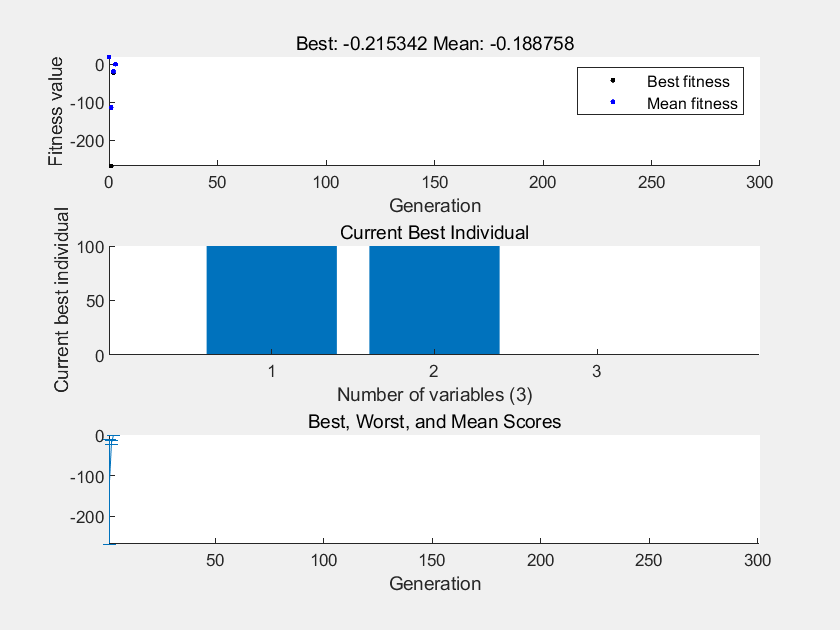

% 设置非默认求解器选项
options2 = optimoptions("ga","MaxGenerations",300,"CrossoverFraction",0.7,...
    "Display","iter","PlotFcn",["gaplotbestf","gaplotbestindiv",...
    "gaplotrange"]);

% 求解
[solution,objectiveValue] = ga(@test_func,n,[],[],[],[],lb,ub,@test_con,[],...
    options2);


% 清除变量
clearvars options2
%maxvalue = objectiveValue;